# Linear Phase Plane Analysis

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

 This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output Inline`.

## Equilibria

Solutions of the damped mass-spring-damper system tend toward a resting position with zero displacement and velocity in the absence of external forcing.

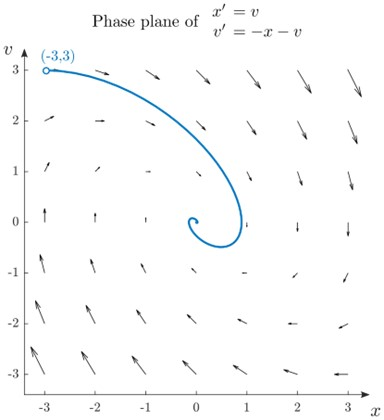

*Mass-spring-damper solution plotted on the phase plane. The solutions approach (0,0), the state where the mass has zero displacement (*$x = 0$*) and velocity (*$v = 0$*).*

**Definition. **Consider a system of two autonomous, first order ODEs:


$$\begin{array}{rl}
x' &= f(x,y)
\\
y' &= g(x,y)
\end{array}$$


An *equilibrium* point occurs when $x' = 0$ and $y' = 0$.

 ** Example. **Find the equilibrium of the mass-spring-damper ODE.


$$\begin{array}{rl}

x' &= v
\\
v' &= \frac{1}{m}( F - kx - cv)
\end{array}$$


**Solution. **Set the derivatives to zero:


$$\begin{array}{rl}

0 &= v
\\
0 &= \frac{1}{m}( F - kx - cv)
\end{array}$$


Using the fact that $v = 0$:


$$\begin{array}{rl}
0 &= \frac{1}{m}( F - kx)
\\
x &= F/k
\end{array}$$


Therefore, an equilibrium occurs at $(x,v) = (F/k,0)$. In the plot shown above, $F=0$, so the equilibrium occurs at $(0,0)$.

** Exercise. **Find the equilibrium of the ODE system


$$\begin{array}{rl}
x' &= x- y + 4
\\
y' &= x+y
\end{array}$$


Write the equilibrium point as a coordinate in the space provided below without the parentheses, e.g., `3,1` for an equilibrium at $x=3$, $y = 1$.

eq = [ ];
CheckLinearEq(eq) % Checks your answer

** Exercise. **Find the equilibria of the simple pendulum ODE system:


$$\begin{array}{rl}

\theta' &= \omega
\\
\omega' &= -\frac{g}{l} \sin \theta
\end{array}$$


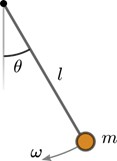

*Simple pendulum diagram*

Write the $\theta$ coordinate of the equilibria in the space provided in terms of the symbolic variable `k` which represents an arbitrary integer ($k \in \mathbb{z}$). You do not need to write the $\omega$ coordinate of the equilibria.

syms k
theta_eq = [ ];
CheckPendulumEquilibria(theta_eq) % Checks your answer

**  Reflect.** 

- Draw a diagram of the pendulum with $\theta = 0$ and another with $\theta = \pi$. 

- Which equilibrium is stable? Which is unstable?

    **Activity. **In this activity, you will find equilibria of an ODE system in the Phase Plane app.

The two-dimensional flight path of a glider can be modeled using a simple ODE system: 


$$\begin{array}{rl}
\frac{d \theta}{dt} &= -\frac{\cos \theta}{v} + v
\\
\frac{d v}{dt} &= -\sin \theta - \frac{v^2}{R}
\end{array}$$


The variable $\theta$ represents the pitch of the glider and $v$ its speed in m/s. The constant $R$ is the ratio of lift to drag ($R = L/D$). 

 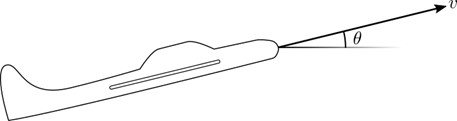

*Illustration of a glider and the ODE variables*

**Task 1.** Set the ODE system in the Phase Plane app to the glider ODE system with $R = 5$. 

**Task 2.** Set the axis limits to $\theta: [-4, 4]$ and $v:[ -3,3]$.

**Task 3. **In the **Analysis **drop-down menu, select **Scan for equilibria**. What is the position of the equilibrium in the top half of the phase plane? To accurately identify the location of the equilibrium, click on it. Write your answer as a coordinate (without parentheses) e.g., `0.1, 0.5`.

gliderEQ = [ ];
CheckGliderEq(gliderEQ) % Checks your answer

**Task 4. **Click on the phase plane to plot three solutions near the equilibrium point. Do solutions approach the equilibrium? 

yourAnswer = "-";
CheckGliderQuestion(yourAnswer) % Checks your answer

**  Reflect.** 

- Physically, what does the equilibrium point represent? Is the glider at rest at the equilibrium point?

## Classification of equilibria

Like 1D equilibria, 2D equilibria can be classified as stable (nearby solutions approach the equilibrium) or unstable (nearby solutions travel away from the equilibrium). For 2D systems, the equilibria can be further classified using the eigenvalues of the system written in matrix form.

### Writing linear systems of differential equations in matrix form

Consider the system of two linear differential equations:


$$\begin{array}{rl}
x' &= ax + by + r
\\
y' &= cx + dy + s
\end{array}$$


where $a$, $b$, $r$, $c$, $d$, and $s$ are constants. The matrix form of this system is


$$\left(
\begin{array}{rl}
x' 
\\
y' 
\end{array}
\right)
=
\left(
\begin{array}{rl}
a & b
\\
c  & d
\end{array}
\right) 
\left(
\begin{array}{rl}
x
\\
y
\end{array}
\right)
+ 
\left(
\begin{array}{rl}
r 
\\
s
\end{array}
\right)$$


The coefficient matrix is usually denoted $\mathbf{A} = \left(
\begin{array}{rl}
a & b
\\
c  & d
\end{array}
\right) $ and the solution vector $\mathbf{x} = \left(
\begin{array}{rl}
x 
\\
y
\end{array}
\right)$. With this notation, the system is


$$\mathbf{x}' = \mathbf{A}\mathbf{x} + \mathbf{r}$$


where $\mathbf{r} = 
\left(
\begin{array}{rl}
r 
\\
s
\end{array}
\right)$.

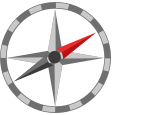**Further exploration. **Learn more about writing systems in matrix form in the *Matrix Methods of Linear Algebra* module. For more information, visit the [GitHub repository](https://github.com/MathWorks-Teaching-Resources/Matrix-Methods-of-Linear-Algebra#readme).

** Exercise. **Verify that the matrix form of the system is equivalent to the original equations by computing the matrix product and summing the result.

** Exercise. **Write the mass-spring-damper ODE in matrix form.


$$\begin{array}{rl}

x' &= v
\\
v' &= \frac{1}{m}( F - kx - cv)
\end{array}$$


**Solution. **Rewrite the system in terms of vectors:


$$\left(
\begin{array}{rl}
x'
\\
v'
\end{array}
\right)
=
\left(
\begin{array}{cc}
v
\\
-\frac{kx}{m} - \frac{cv}{m}
\end{array}
\right) 
+ 
\left(
\begin{array}{rl}
0
\\
\frac{F}{m} 
\end{array}
\right)$$


and factor the middle vector:


$$\left(
\begin{array}{rl}
x '
\\
v'
\end{array}
\right)
=
\left(
\begin{array}{cc}
0 & 1
\\
-\frac{k}{m} &- \frac{c}{m}
\end{array}
\right) 
\left(
\begin{array}{rl}
x 
\\
v
\end{array}
\right)
+ 
\left(
\begin{array}{rl}
0
\\
\frac{F}{m} 
\end{array}
\right)$$


** Exercise. **Write the linear ODE system in matrix form using the solution vector $\mathbf{u} = \left(
\begin{array}{rl}
u
\\
w
\end{array}
\right)$.


$$\begin{array}{rl}
u' &= 2w + u
\\
w' &= w - 3
\end{array}$$


Check your answer by typing the coefficient matrix $\mathbf{A}$ and the constant vector $\mathbf{r}$ in the spaces provided below.   

  **Pro-tip. **The notation for writing the 2x2 matrix $\mathbf{B} = \left(
\begin{array}{rl}
1 & 2
\\
3  & 4
\end{array}
\right)$ in MATLAB is

A = [] % Type your matrix here
r = [] % Type your vector here
CheckMatrixSystem(A,r) % Checks your answer

### Classifying equilibria using eigenvalues

Consider the general linear system of ODEs:


$$\left(
\begin{array}{rl}
x' 
\\
y' 
\end{array}
\right)
=
\left(
\begin{array}{rl}
a & b
\\
c  & d
\end{array}
\right) 
\left(
\begin{array}{rl}
x
\\
y
\end{array}
\right)
+ 
\left(
\begin{array}{rl}
r 
\\
s
\end{array}
\right)$$


A linear system of autonomous ODEs has exactly one equilibrium point. The eigenvalues of the system's coefficient matrix $\mathbf{A}$ can be used to classify the equilibrium. The eigenvalues can be found as the roots of the characteristic polynomial of $\mathbf{A}$:


$$(a - \lambda)(d-\lambda) - bc = 0$$


Expand the terms and apply the quadratic formula to find the eigenvalues


$$\lambda = \frac{1}{2} \left( (a+d) \pm \sqrt{(a+d)^2 - 4(ad-bc)} \right)$$


The system's behavior can be classified based on whether the eigenvalues are real, complex, or imaginary. The sign of the real part also affects the behavior. The table below characterizes the behavior of the system based on its eigenvalues.

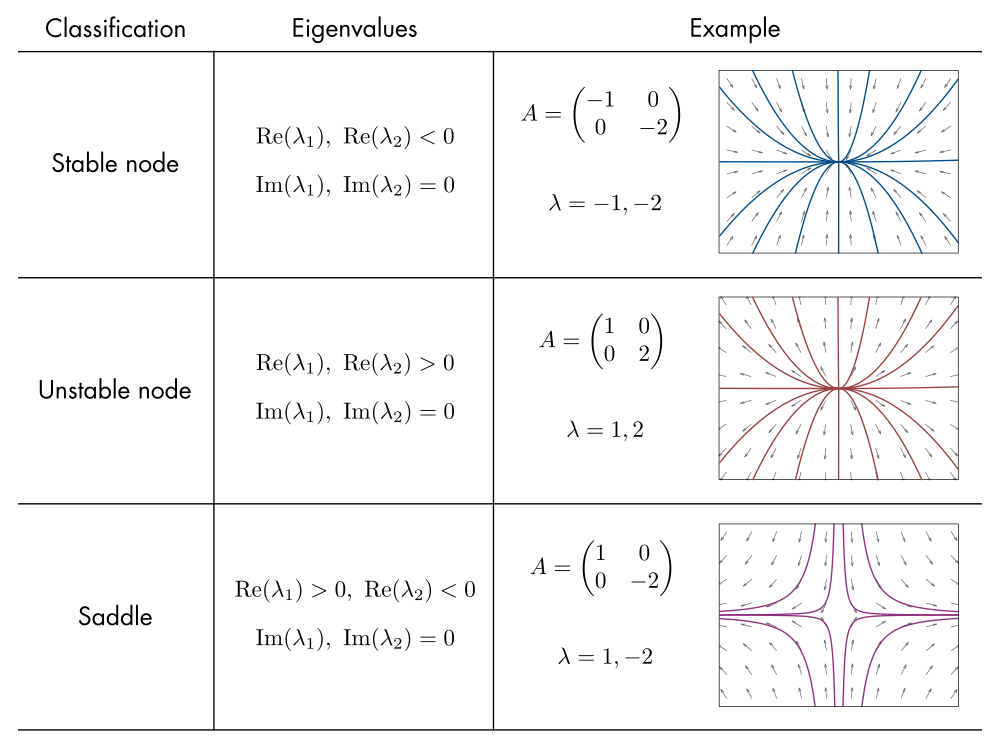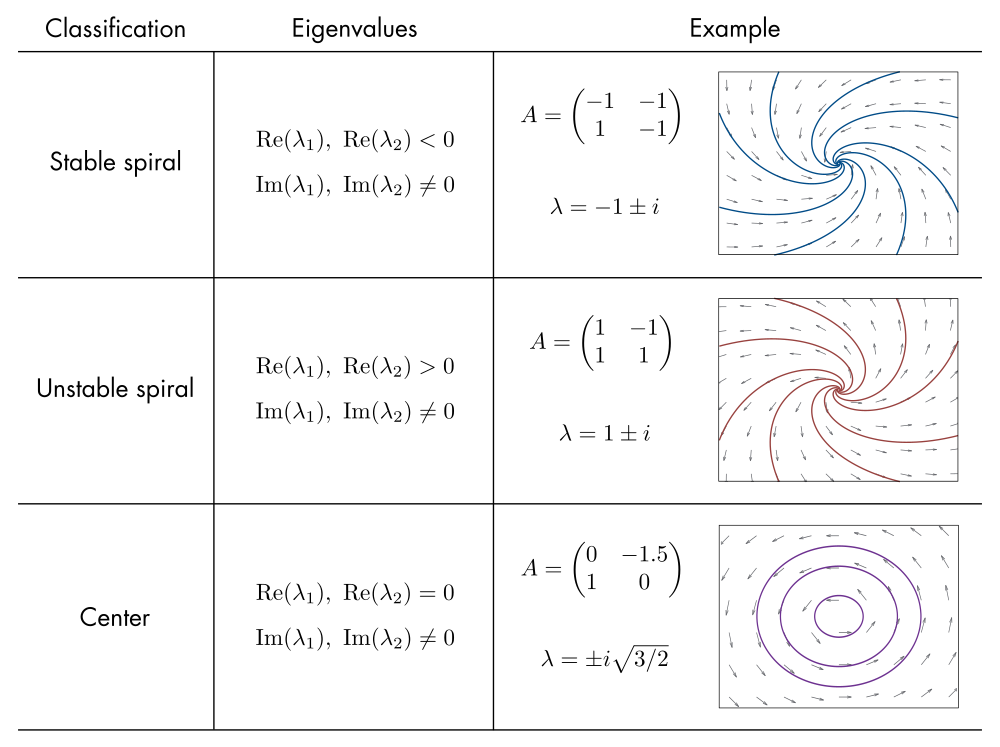

*Standard equilibria classifications*

Examine the eigenvalues in the table above and observe that

- Imaginary components lead to oscillatory behavior (circular trajectories in the phase plane).

- Positive real components lead to unstable behavior.

- Negative real components lead to stable behavior.

** Exercise. **Consider the linear ODE system:


$$\begin{array}{rl}

x' &= -3 x + y
\\
y' &= - 2y
\end{array}$$


**a. **Use the Phase Plane app to plot several solutions of the ODE. Based on the phase portrait, what type of equilibrium do you expect?

**b.** Write the system in matrix form.

**c.** Solve for the eigenvalues of the coefficient matrix. Write both eigenvalues in the space provided below as a comma-separated list.

lambda = [ ];
CheckEigenvalues(lambda) % Checks your answer

**d. **Classify the matrix based on the eigenvalues computed in **c**.

eqType = "-";
CheckEQType(eqType) % Checks your answer

   **Activity. **Consider the linear ODE system:


$$\mathbf{x}' = \mathbf{A}\mathbf{x}$$


The sliders below define the elements of the coefficient matrix, $\mathbf{A}$.

A = [0, 1;...
     1, 0]

**Task. **Adjust the coefficients to produce a:

- Stable/unstable spiral

- Stable/unstable node

- Saddle

- Center

The plot below shows the phase plane for the linear system.

VisualizeLinearODE(A) % Generates the phase plane

Verify that the system is indeed what it appears by examining the eigenvalues computed below. 

lambda = eigs(A)

**  Reflect.** 

- Are there possible equilibria besides those listed in the table?

- If so, what are their eigenvalues?

## Mass-spring-damper equilibrium classification

The mass-spring-damper system has several characteristic behaviors that depend on the parameters of the system. These behaviors can be understood by classifying the system's equilibrium in terms of the eigenvalues of the coefficient matrix.

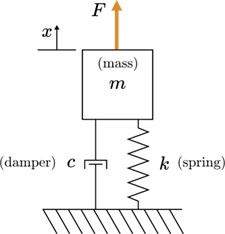

*Illustration of a mass-spring-damper model*

Recall the matrix form of the mass-spring-damper system:


$$\left(
\begin{array}{rl}
x '
\\
v'
\end{array}
\right)
=
\left(
\begin{array}{cc}
0 & 1
\\
-\frac{k}{m} &- \frac{c}{m}
\end{array}
\right) 
\left(
\begin{array}{rl}
x 
\\
v
\end{array}
\right)
+ 
\left(
\begin{array}{rl}
0
\\
\frac{F}{m} 
\end{array}
\right)$$


In this form, the coefficient matrix is


$$\mathbf{A} =\left(
\begin{array}{cc}
0 & 1
\\
-\frac{k}{m} &- \frac{c}{m}
\end{array}
\right) $$


** Exercise. **In this exercise, you will analyze the behavior of the mass-spring-damper by classifying its equilibrium point. For all parts, consider the model without external forcing; $F = 0$.

**Part 1. **Consider the case where $k = m = 1$ and $c = 0$. 

**a.  **Compute the eigenvalues of $\mathbf{A}$. Store the result `lambda`. You can do these computations by hand or using MATLAB commands in the space below.

  **Pro-tip. **The notation for writing a 2x2 matrix in MATLAB is

You can compute the eigenvalues of a matrix in MATLAB using the [`eig`](https://www.mathworks.com/help/matlab/ref/eig.html) function. For example:

A = [];
lambda = NaN;   % eigenvalues (replace NaN with your answer or function call)
CheckMSDPart1(lambda) % Checks your answers

**b.** Based on the values computed in **a,** how would you classify the equilibrium?

eqType = "-";
CheckEQType1(eqType) % Checks your answer

**c. **Define the mass-spring-damper system in the Phase Plane app and set the parameter values. Plot several solutions. Do they match the behavior you predicted in **b**? 

**d.** Observe the time series of the solution in the app. Would you classify the system as undamped, underdamped, critically damped, or overdamped?

**Part 2. **Consider the case where $k = m = 1$ and $c = 0.5$. 

**a.  **Compute the eigenvalues of $\mathbf{A}$. Store the result in `lambda`. You can do these computations by hand or using MATLAB commands in the space below.

A = [];
lambda = NaN;   % eigenvalues (replace NaN with your answer or function call)
CheckMSDPart2(lambda) % Checks your answer

**b.** Based on the values computed in **a,** how would you classify the equilibrium?

eqType = "-";
CheckEQType2(eqType) % Checks your answer

**c. **Adjust the value of $\mathbf{c}$ in the Phase Plane app and plot several additional solutions. Do they match the behavior you predicted in **b**? 

**d.** Observe the time series of the solution in the app. Would you classify the system as undamped, underdamped, critically damped, or overdamped?

**Part 3. **Consider the case where $k = m = 1$ and $c = 3$. 

**a.  **Compute the eigenvalues of $\mathbf{A}$. Store the result in `lambda`. You can do these computations by hand or using MATLAB commands in the space below.

A = [];
lambda = NaN;   % eigenvalues (replace NaN with your answer or function call)
CheckMSDPart3(lambda) % Checks your answers

**b.** Based on the values computed in **a,** how would you classify the equilibrium?

eqType = "-";
CheckEQType3(eqType) % Checks your answer

**c. **Adjust the value of $\mathbf{c}$ in the Phase Plane app and plot several additional solutions. Do they match the behavior you predicted in **b**? 

**d.** Observe the time series of the solution in the app. Would you classify the system as undamped, underdamped, critically damped, or overdamped?

### Critically damped mass-spring-damper

During the last exercise, the mass-spring-damper eigenvalues changed from purely imaginary, to complex, to purely real. These transitions can be visualized in the complex plane.

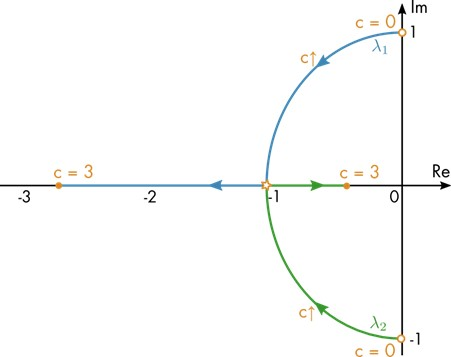

*Eigenvalues of the mass-spring-damper system plotted in the complex plane as *$c$* is increased. *

*When the system transitions from underdamped to overdamped, it is called critically damped. At this point, *$\lambda_1 = \lambda_2$*. This is marked on the complex plane with a star.*

** Exercise. **Consider the mass-spring-damper system with $m = k = 1$ and $F = 0$:


$$\left(
\begin{array}{rl}
x '
\\
v'
\end{array}
\right)
=
\left(
\begin{array}{cc}
0 & 1
\\
-1&- c
\end{array}
\right) 
\left(
\begin{array}{rl}
x 
\\
v
\end{array}
\right)$$


**a.** Solve for an expression for the eigenvalues of the coefficient matrix in terms of the damping coefficient, $c$.

**b. **Solve for the value of $c$ where the mass-spring-damper system is critically damped. The system is critically damped when the expression under the square root is zero.

ccrit = [ ];
CheckCCrit(ccrit) % Checks your answer

**b. **Use the Phase Plane app to plot the solution with $x(0) = 1$ and $v(0) = 0$ for the critically damped mass-spring-damper system and observe the time series. If correct, your solution should appear as shown below. 

 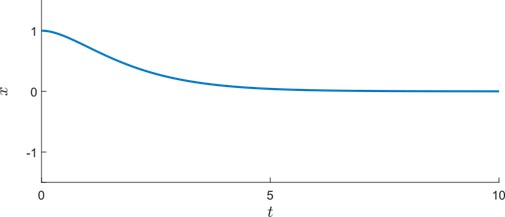

Notice that when the system is critically damped, it rapidly approaches the equilibrium and does not oscillate around it. From an engineering perspective, this is often a desirable behavior; the equilibrium is reached as quickly as possible without oscillations. 

**  Reflect.** 

- Compare the underdamped ($c=0.5$) and overdamped ($c = 5$) time series with the same initial condition ($x(0) = 1$ and $v(0) = 0$)  to the one shown above for the critically damped system.

- Which system reaches the equilibrium the fastest? Which the slowest?

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

**Visualizations**

function VisualizeLinearODE(A)
    % Visualizes a linear 2D ODE system with coefficient matrix A
    x = -3:0.5:3;
    y = -3:0.5:3;
    
    [X,Y] = meshgrid(x,y);

    f = A(1,1)*X + A(1,2)*Y;
    g = A(2,1)*X + A(2,2)*Y;
    quiver(X,Y,f,g)

    axis equal
    axis([x(1) x(end) y(1) y(end)])
    xlabel("$x_1$","Interpreter","latex")
    ylabel("$x_2$","Interpreter","latex")

    title("Phase plane for $\mathbf{x'= Ax}$","Interpreter","latex")
end

**Checks**

function CheckMatrixSystem(A,r)
    IsEqualCheck(A,[1 2; 0 1])
    IsEqualCheck(r,[0; -3])
end

function CheckLinearEq(eq)
    IsEqualCheck([-2 2],eq)
end

function CheckPendulumEquilibria(eq)
    syms k
    IsEqualCheck(pi*k,eq)
end

function CheckGliderEq(gliderEQ)
    value = [-0.2 0.99];
    if(any(size(value)~=size(gliderEQ)))
        warning("Your answer does not have the correct number of equilibria.")
        return
    end
     if( all( abs( gliderEQ - value ) < 0.1 ) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
     end
end

function CheckGliderQuestion(yourAnswer)
    IsEqualCheck(yourAnswer,"yes")
end

% function CheckTrDet(delta)
%     IsEqualCheck(delta,1)
% end

function CheckEQType(eqType)
    IsEqualCheck(eqType,"stable node")
end

function CheckEigenvalues(lambda)
    IsEqualCheck(sort(lambda),sort([-3 -2]))
end

function CheckMSDPart1(lambda)
    if( all( abs( sort(lambda) - sort([-1i;1i]) ) < 1e-3 ) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
    end
end

function CheckMSDPart2(lambda)
    if( all( abs(sort(lambda) - sort([-0.25+0.968245836551854i; -0.25-0.968245836551854i])) < 1e-3 ) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
    end
end

function CheckMSDPart3(lambda)
    if( all( abs(sort(lambda) - sort([-2.618033988749895; -0.381966011250105])) < 1e-3 ) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
    end
end

function CheckEQType1(eqType)
    IsEqualCheck(eqType,"center")
end

function CheckEQType2(eqType)
    IsEqualCheck(eqType,"stable spiral")
end

function CheckEQType3(eqType)
    IsEqualCheck(eqType,"stable node")
end

function CheckCCrit(ccrit)
    IsEqualCheck(ccrit,2)
end

function IsEqualCheck(userSubmission,correctAnswer)
% This function checks if two results are equal and displays feedback
    if( isequal(userSubmission, correctAnswer) )
        disp("Correct!")
    else
        warning("Your answer does not match the expected result.")
    end
end

%#ok<*NBRAK> 
%#ok<*NASGU> 